# time series climatic data check

## Tarfala Research Station

## reset before run

delete precipitation.csv RH.csv temperature.csv
clearvars

2009-2014

[timePrec,prec] = climateInput('su\precipitation\','precipitation.csv');
[timeRH,RH] = climateInput('su\RH\','RH.csv');
[timeTemp,temp] = climateInput('su\temperature\','temperature.csv');

2015-2018

note: a repetition of measurement at the beginning of 2015, delete i

rawdata = readtable('su\TRSAWS_hourly_2015-2018.csv');
rawdata(1,:) = []; % remove a repetition of measurement at the beginning of 2015
time = rawdata.TIMESTAMP;
[y,m,d] = ymd(time);
[hr,mi,se] = hms(time);
prec = rawdata.Prec_tot;
RH = rawdata.RH_avg;
temp = rawdata.aT_avg;
dlmwrite('precipitation.csv',[y,m,d,hr,mi,se,prec],'-append');
dlmwrite('RH.csv',[y,m,d,hr,mi,se,RH],'-append');
dlmwrite('temperature.csv',[y,m,d,hr,mi,se,temp],'-append');

## plot for check

clearvars
rawdata = dlmread('RH.csv');
timeTarfala = datetime(rawdata(:,1:6));
RH = rawdata(:,7);
rawdata = dlmread('precipitation.csv');
prec = rawdata(:,7);
prec(prec>20) = nan;
rawdata = dlmread('temperature.csv');
temp =  rawdata(:,7);
t1 = timeTarfala(1); t2 = timeTarfala(end);
[yr,mo,da,hr,mi,se,precTRS,precTRSgaps] = timeSeriesData(timeTarfala,hours(1),t1,t2,prec);

Time range of the dataset 
01-Jan-2008 01:00:00-20-Sep-2018 09:00:00
370 date gaps found 
   07-Jan-2009 05:00:00
   08-Jan-2009 05:00:00
   09-Jan-2009 05:00:00
   10-Jan-2009 05:00:00
   11-Jan-2009 05:00:00
   12-Jan-2009 05:00:00
   13-Jan-2009 05:00:00
   14-Jan-2009 05:00:00
   15-Jan-2009 05:00:00
   16-Jan-2009 05:00:00
   17-Jan-2009 05:00:00
   18-Jan-2009 05:00:00
   19-Jan-2009 05:00:00
   20-Jan-2009 05:00:00
   21-Jan-2009 05:00:00
   22-Jan-2009 05:00:00
   23-Jan-2009 05:00:00
   24-Jan-2009 05:00:00
   25-Jan-2009 05:00:00
   26-Jan-2009 05:00:00
   27-Jan-2009 05:00:00
   28-Jan-2009 05:00:00
   29-Jan-2009 05:00:00
   30-Jan-2009 05:00:00
   31-Jan-2009 05:00:00
   01-Feb-2009 05:00:00
   02-Feb-2009 05:00:00
   03-Feb-2009 05:00:00
   04-Feb-2009 05:00:00
   05-Feb-2009 05:00:00
   06-Feb-2009 05:00:00
   07-Feb-2009 05:00:00
   08-Feb-2009 05:00:00
   09-Feb-2009 05:00:00
   10-Feb-2009 05:00:00
   11-Feb-2009 05:00:00
   12-Feb-2009 05:00:00
   13-Feb-2009 05:00:0

2201 data gaps found 
   07-Jan-2009 05:00:00
   07-Jan-2009 17:00:00
   07-Jan-2009 18:00:00
   07-Jan-2009 19:00:00
   07-Jan-2009 20:00:00
   07-Jan-2009 21:00:00
   07-Jan-2009 22:00:00
   07-Jan-2009 23:00:00
   08-Jan-2009 00:00:00
   08-Jan-2009 01:00:00
   08-Jan-2009 02:00:00
   08-Jan-2009 03:00:00
   08-Jan-2009 04:00:00
   08-Jan-2009 05:00:00
   08-Jan-2009 06:00:00
   08-Jan-2009 07:00:00
   08-Jan-2009 08:00:00
   08-Jan-2009 09:00:00
   08-Jan-2009 10:00:00
   08-Jan-2009 11:00:00
   08-Jan-2009 12:00:00
   08-Jan-2009 13:00:00
   08-Jan-2009 14:00:00
   08-Jan-2009 15:00:00
   08-Jan-2009 16:00:00
   08-Jan-2009 17:00:00
   08-Jan-2009 18:00:00
   08-Jan-2009 19:00:00
   08-Jan-2009 20:00:00
   08-Jan-2009 21:00:00
   08-Jan-2009 22:00:00
   08-Jan-2009 23:00:00
   09-Jan-2009 00:00:00
   09-Jan-2009 01:00:00
   09-Jan-2009 02:00:00
   09-Jan-2009 03:00:00
   09-Jan-2009 04:00:00
   09-Jan-2009 05:00:00
   09-Jan-2009 06:00:00
   09-Jan-2009 07:00:00
   09-Jan-2009 08:

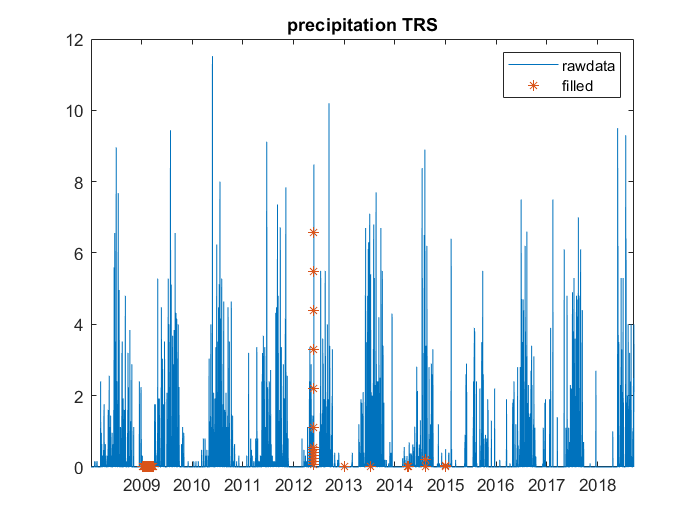

title('precipitation TRS');

[yr,mo,da,hr,mi,se,RHTRS,RHTRSgaps] = timeSeriesData(timeTarfala,hours(1),t1,t2,RH);

Time range of the dataset 
01-Jan-2008 01:00:00-20-Sep-2018 09:00:00
370 date gaps found 
   07-Jan-2009 05:00:00
   08-Jan-2009 05:00:00
   09-Jan-2009 05:00:00
   10-Jan-2009 05:00:00
   11-Jan-2009 05:00:00
   12-Jan-2009 05:00:00
   13-Jan-2009 05:00:00
   14-Jan-2009 05:00:00
   15-Jan-2009 05:00:00
   16-Jan-2009 05:00:00
   17-Jan-2009 05:00:00
   18-Jan-2009 05:00:00
   19-Jan-2009 05:00:00
   20-Jan-2009 05:00:00
   21-Jan-2009 05:00:00
   22-Jan-2009 05:00:00
   23-Jan-2009 05:00:00
   24-Jan-2009 05:00:00
   25-Jan-2009 05:00:00
   26-Jan-2009 05:00:00
   27-Jan-2009 05:00:00
   28-Jan-2009 05:00:00
   29-Jan-2009 05:00:00
   30-Jan-2009 05:00:00
   31-Jan-2009 05:00:00
   01-Feb-2009 05:00:00
   02-Feb-2009 05:00:00
   03-Feb-2009 05:00:00
   04-Feb-2009 05:00:00
   05-Feb-2009 05:00:00
   06-Feb-2009 05:00:00
   07-Feb-2009 05:00:00
   08-Feb-2009 05:00:00
   09-Feb-2009 05:00:00
   10-Feb-2009 05:00:00
   11-Feb-2009 05:00:00
   12-Feb-2009 05:00:00
   13-Feb-2009 05:00:0

6564 data gaps found 
   07-Jan-2009 05:00:00
   07-Jan-2009 17:00:00
   07-Jan-2009 18:00:00
   07-Jan-2009 19:00:00
   07-Jan-2009 20:00:00
   07-Jan-2009 21:00:00
   07-Jan-2009 22:00:00
   07-Jan-2009 23:00:00
   08-Jan-2009 00:00:00
   08-Jan-2009 01:00:00
   08-Jan-2009 02:00:00
   08-Jan-2009 03:00:00
   08-Jan-2009 04:00:00
   08-Jan-2009 05:00:00
   08-Jan-2009 06:00:00
   08-Jan-2009 07:00:00
   08-Jan-2009 08:00:00
   08-Jan-2009 09:00:00
   08-Jan-2009 10:00:00
   08-Jan-2009 11:00:00
   08-Jan-2009 12:00:00
   08-Jan-2009 13:00:00
   08-Jan-2009 14:00:00
   08-Jan-2009 15:00:00
   08-Jan-2009 16:00:00
   08-Jan-2009 17:00:00
   08-Jan-2009 18:00:00
   08-Jan-2009 19:00:00
   08-Jan-2009 20:00:00
   08-Jan-2009 21:00:00
   08-Jan-2009 22:00:00
   08-Jan-2009 23:00:00
   09-Jan-2009 00:00:00
   09-Jan-2009 01:00:00
   09-Jan-2009 02:00:00
   09-Jan-2009 03:00:00
   09-Jan-2009 04:00:00
   09-Jan-2009 05:00:00
   09-Jan-2009 06:00:00
   09-Jan-2009 07:00:00
   09-Jan-2009 08:

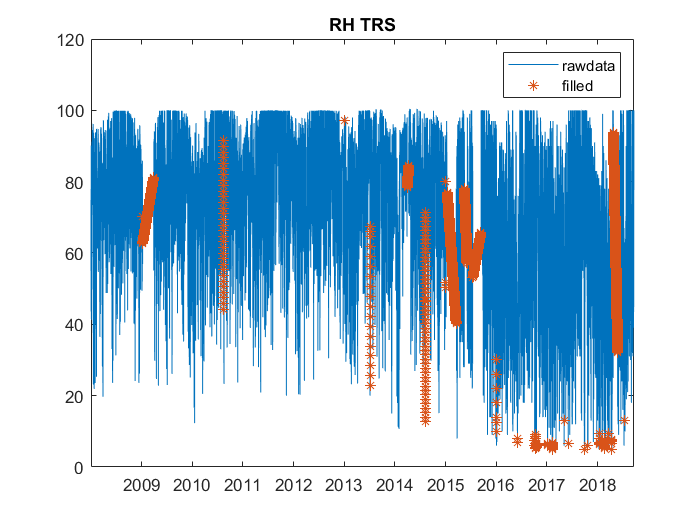

title('RH TRS');

[yr,mo,da,hr,mi,se,tempTRS,tempTRSgaps] = timeSeriesData(timeTarfala,hours(1),t1,t2,temp);

Time range of the dataset 
01-Jan-2008 01:00:00-20-Sep-2018 09:00:00
370 date gaps found 
   07-Jan-2009 05:00:00
   08-Jan-2009 05:00:00
   09-Jan-2009 05:00:00
   10-Jan-2009 05:00:00
   11-Jan-2009 05:00:00
   12-Jan-2009 05:00:00
   13-Jan-2009 05:00:00
   14-Jan-2009 05:00:00
   15-Jan-2009 05:00:00
   16-Jan-2009 05:00:00
   17-Jan-2009 05:00:00
   18-Jan-2009 05:00:00
   19-Jan-2009 05:00:00
   20-Jan-2009 05:00:00
   21-Jan-2009 05:00:00
   22-Jan-2009 05:00:00
   23-Jan-2009 05:00:00
   24-Jan-2009 05:00:00
   25-Jan-2009 05:00:00
   26-Jan-2009 05:00:00
   27-Jan-2009 05:00:00
   28-Jan-2009 05:00:00
   29-Jan-2009 05:00:00
   30-Jan-2009 05:00:00
   31-Jan-2009 05:00:00
   01-Feb-2009 05:00:00
   02-Feb-2009 05:00:00
   03-Feb-2009 05:00:00
   04-Feb-2009 05:00:00
   05-Feb-2009 05:00:00
   06-Feb-2009 05:00:00
   07-Feb-2009 05:00:00
   08-Feb-2009 05:00:00
   09-Feb-2009 05:00:00
   10-Feb-2009 05:00:00
   11-Feb-2009 05:00:00
   12-Feb-2009 05:00:00
   13-Feb-2009 05:00:0

3932 data gaps found 
   07-Jan-2009 05:00:00
   07-Jan-2009 17:00:00
   07-Jan-2009 18:00:00
   07-Jan-2009 19:00:00
   07-Jan-2009 20:00:00
   07-Jan-2009 21:00:00
   07-Jan-2009 22:00:00
   07-Jan-2009 23:00:00
   08-Jan-2009 00:00:00
   08-Jan-2009 01:00:00
   08-Jan-2009 02:00:00
   08-Jan-2009 03:00:00
   08-Jan-2009 04:00:00
   08-Jan-2009 05:00:00
   08-Jan-2009 06:00:00
   08-Jan-2009 07:00:00
   08-Jan-2009 08:00:00
   08-Jan-2009 09:00:00
   08-Jan-2009 10:00:00
   08-Jan-2009 11:00:00
   08-Jan-2009 12:00:00
   08-Jan-2009 13:00:00
   08-Jan-2009 14:00:00
   08-Jan-2009 15:00:00
   08-Jan-2009 16:00:00
   08-Jan-2009 17:00:00
   08-Jan-2009 18:00:00
   08-Jan-2009 19:00:00
   08-Jan-2009 20:00:00
   08-Jan-2009 21:00:00
   08-Jan-2009 22:00:00
   08-Jan-2009 23:00:00
   09-Jan-2009 00:00:00
   09-Jan-2009 01:00:00
   09-Jan-2009 02:00:00
   09-Jan-2009 03:00:00
   09-Jan-2009 04:00:00
   09-Jan-2009 05:00:00
   09-Jan-2009 06:00:00
   09-Jan-2009 07:00:00
   09-Jan-2009 08:

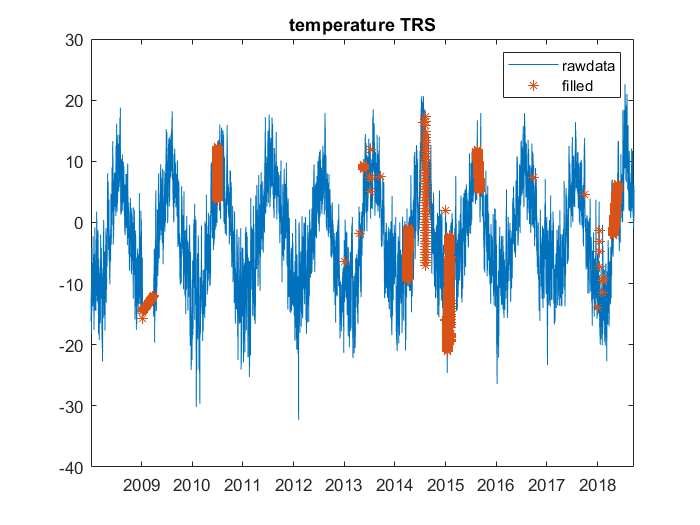

title('temperature TRS');

% dlmwrite('check\precTarf.txt',precgaps);
% dlmwrite('check\RHTarf.txt',RHgaps);
% dlmwrite('check\tempTarf.txt',tempgaps);
% dlmwrite('check\precTarf.txt',datenum(rawprec));
% dlmwrite('check\RHTarf.txt',datenum(rawRH));
% dlmwrite('check\tempTarf.txt',datenum(rawtemp));
timeTarfala = datetime(yr,mo,da,hr,mi,se);
location.N = 7537422;   location.E = 1651517;
location.Z = 1143;  location.ref = 'sweref_99_tm';
save('TarfalaAWS.mat','timeTarfala','tempTRS','precTRS','RHTRS','location','tempTRSgaps',...
    'precTRSgaps','RHTRSgaps');

## Ablation AWS

All year round 2013-2018

aT_fit is used instead of aT_avg

clearvars
location.N = 67.9030;   location.E = 18.5726;
location.Z = 1350;  location.ref = 'WGS84';
rawdata = readtable('AblationAWS\AblationAWS.csv');
timeAWS = rawdata.TIMESTAMP;
RH = rawdata.RH_avg;
temp = rawdata.aT_fit;
% clear rawdata
% save('AblationAWS.mat');
t1 = timeAWS(1); t2 = timeAWS(end);
[yr,mo,da,hr,mi,se,RHAWS,RHAWSgaps] = timeSeriesData(timeAWS,hours(1),t1,t2,RH);

Time range of the dataset 
2013-04-17 16:00-2018-09-12 09:00
Time seri-es is complete without date gaps
2760 data gaps found 
   2013-05-13 20:00
   2013-05-13 21:00
   2013-05-13 22:00
   2013-05-13 23:00
   2013-05-14 00:00
   2013-05-14 01:00
   2013-05-14 02:00
   2013-05-14 03:00
   2013-05-14 04:00
   2013-05-14 05:00
   2013-05-14 06:00
   2013-05-14 07:00
   2013-05-14 08:00
   2013-05-14 09:00
   2013-05-14 10:00
   2013-05-14 11:00
   2013-05-14 12:00
   2013-05-14 13:00
   2013-05-14 14:00
   2013-05-14 15:00
   2013-05-14 16:00
   2013-05-14 17:00
   2013-05-14 18:00
   2013-05-14 19:00
   2013-05-14 20:00
   2013-05-14 21:00
   2013-05-14 22:00
   2013-05-14 23:00
   2013-05-15 00:00
   2013-05-15 01:00
   2013-05-15 02:00
   2013-05-15 03:00
   2013-05-15 04:00
   2013-05-15 05:00
   2013-05-15 06:00
   2013-05-15 07:00
   2013-05-15 08:00
   2013-05-15 09:00
   2013-05-15 10:00
   2013-05-15 11:00
   2013-05-15 12:00
   2013-05-15 13:00
   2013-05-15 14:00
   2013-05-15 

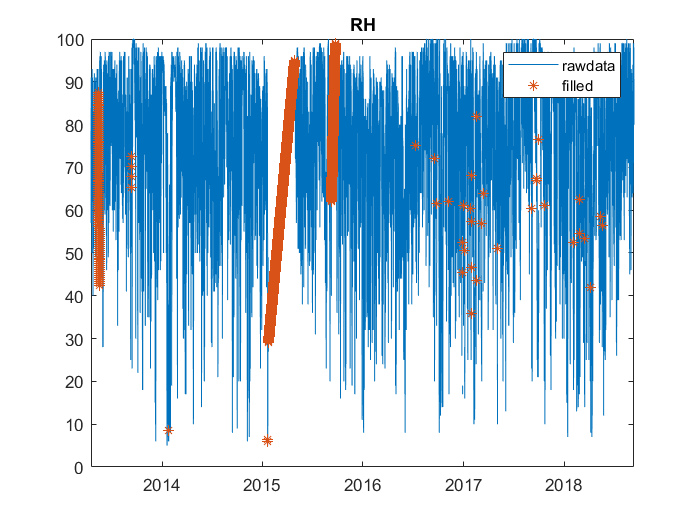

title('RH');

[yr,mo,da,hr,mi,se,tempAWS,tempAWSgaps] = timeSeriesData(timeAWS,hours(1),t1,t2,temp);

Time range of the dataset 
2013-04-17 16:00-2018-09-12 09:00
Time seri-es is complete without date gaps
2193 data gaps found 
   2013-09-12 12:00
   2013-09-12 13:00
   2013-09-12 14:00
   2013-09-12 15:00
   2015-01-22 13:00
   2015-01-22 14:00
   2015-01-22 15:00
   2015-01-22 16:00
   2015-01-22 17:00
   2015-01-22 18:00
   2015-01-22 19:00
   2015-01-22 20:00
   2015-01-22 21:00
   2015-01-22 22:00
   2015-01-22 23:00
   2015-01-23 01:00
   2015-01-23 02:00
   2015-01-23 03:00
   2015-01-23 04:00
   2015-01-23 05:00
   2015-01-23 06:00
   2015-01-23 07:00
   2015-01-23 08:00
   2015-01-23 09:00
   2015-01-23 10:00
   2015-01-23 11:00
   2015-01-23 12:00
   2015-01-23 13:00
   2015-01-23 14:00
   2015-01-23 15:00
   2015-01-23 16:00
   2015-01-23 17:00
   2015-01-23 18:00
   2015-01-23 19:00
   2015-01-23 20:00
   2015-01-23 21:00
   2015-01-23 22:00
   2015-01-23 23:00
   2015-01-24 01:00
   2015-01-24 02:00
   2015-01-24 03:00
   2015-01-24 04:00
   2015-01-24 05:00
   2015-01-24 

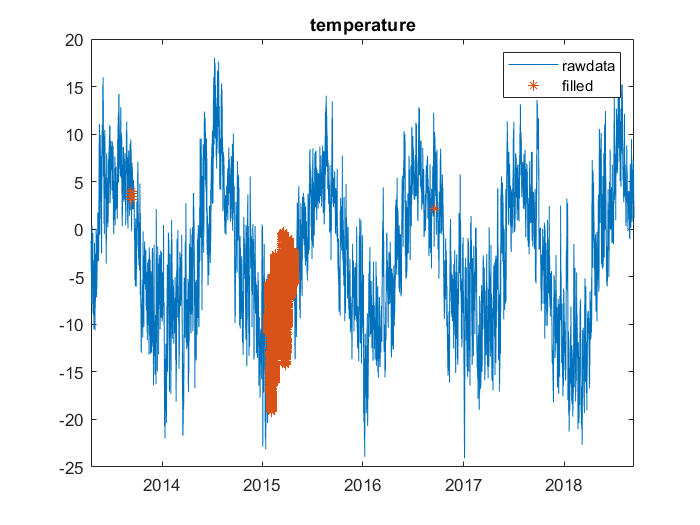

title('temperature');

% dlmwrite('check\RHAWS.txt',RHAWSgaps);
% dlmwrite('check\tempAWS.txt',tempAWSgaps);
% dlmwrite('check\RHAWS.txt',datenum(rawRH));
% dlmwrite('check\tempAWS.txt',datenum(rawtemp));
timeAWS = datetime(yr,mo,da,hr,mi,se);
save('AblationAWS.mat','timeAWS','RHAWS','tempAWS','location','RHAWSgaps','tempAWSgaps');

## AblationAWS summer

only opreates in summer from April to September

clearvars
delete AblationAWS\SgAWS_hourly_summer.csv
filepath = 'AblationAWS\summer\';
subdir = dir(filepath);
for i = 3:length(subdir)
    rawdata = readtable([filepath,subdir(i).name]);
    time = rawdata.TIMESTAMP;
    data = table2array(rawdata(:,2:end));
    [yr,mo,da] = ymd(time);
    [hr,mi,se] = hms(time);
    dlmwrite('AblationAWS\SgAWS_hourly_summer.csv',[yr,mo,da,hr,mi,se,data],'-append');
end
clearvars
rawdata = readtable('AblationAWS\SgAWS_hourly_summer.csv');
timeSummer = table2array(rawdata(:,1:6));
timeSummer = datetime(timeSummer);
t1 = timeSummer(1); t2 = timeSummer(end);
RHSummer = table2array(rawdata(:,10:12));
tempSummer = table2array(rawdata(:,7:9));
% take the average value at different height
RHSummer = nanmean(RHSummer,2);
tempSummer = nanmean(tempSummer,2);
% gap detection but no gap filling
[yr,mo,da,hr,mi,se,tempSummer,tempSummergaps] = timeSeriesData(timeSummer,hours(1),t1,t2,tempSummer);

Time range of the dataset 
17-Apr-2013 16:00:00-12-Sep-2018 09:00:00
27445 date gaps found 
   12-Sep-2013 12:00:00
   12-Sep-2013 13:00:00
   12-Sep-2013 14:00:00
   12-Sep-2013 15:00:00
   12-Sep-2013 16:00:00
   12-Sep-2013 17:00:00
   12-Sep-2013 18:00:00
   12-Sep-2013 19:00:00
   12-Sep-2013 20:00:00
   12-Sep-2013 21:00:00
   12-Sep-2013 22:00:00
   12-Sep-2013 23:00:00
   13-Sep-2013 00:00:00
   13-Sep-2013 01:00:00
   13-Sep-2013 02:00:00
   13-Sep-2013 03:00:00
   13-Sep-2013 04:00:00
   13-Sep-2013 05:00:00
   13-Sep-2013 06:00:00
   13-Sep-2013 07:00:00
   13-Sep-2013 08:00:00
   13-Sep-2013 09:00:00
   13-Sep-2013 10:00:00
   13-Sep-2013 11:00:00
   13-Sep-2013 12:00:00
   13-Sep-2013 13:00:00
   13-Sep-2013 14:00:00
   13-Sep-2013 15:00:00
   13-Sep-2013 16:00:00
   13-Sep-2013 17:00:00
   13-Sep-2013 18:00:00
   13-Sep-2013 19:00:00
   13-Sep-2013 20:00:00
   13-Sep-2013 21:00:00
   13-Sep-2013 22:00:00
   13-Sep-2013 23:00:00
   14-Sep-2013 00:00:00
   14-Sep-2013 01:00

28386 data gaps found 
   19-Apr-2013 13:00:00
   19-Apr-2013 14:00:00
   19-Apr-2013 15:00:00
   19-Apr-2013 16:00:00
   19-Apr-2013 17:00:00
   19-Apr-2013 18:00:00
   19-Apr-2013 19:00:00
   19-Apr-2013 20:00:00
   19-Apr-2013 21:00:00
   19-Apr-2013 22:00:00
   19-Apr-2013 23:00:00
   20-Apr-2013 00:00:00
   20-Apr-2013 01:00:00
   20-Apr-2013 02:00:00
   20-Apr-2013 03:00:00
   20-Apr-2013 04:00:00
   20-Apr-2013 05:00:00
   20-Apr-2013 06:00:00
   20-Apr-2013 07:00:00
   20-Apr-2013 08:00:00
   20-Apr-2013 09:00:00
   20-Apr-2013 10:00:00
   20-Apr-2013 11:00:00
   20-Apr-2013 12:00:00
   20-Apr-2013 13:00:00
   20-Apr-2013 14:00:00
   20-Apr-2013 15:00:00
   20-Apr-2013 16:00:00
   20-Apr-2013 17:00:00
   20-Apr-2013 18:00:00
   20-Apr-2013 19:00:00
   20-Apr-2013 20:00:00
   20-Apr-2013 21:00:00
   20-Apr-2013 22:00:00
   20-Apr-2013 23:00:00
   21-Apr-2013 00:00:00
   21-Apr-2013 01:00:00
   21-Apr-2013 02:00:00
   21-Apr-2013 03:00:00
   21-Apr-2013 04:00:00
   21-Apr-2013 05

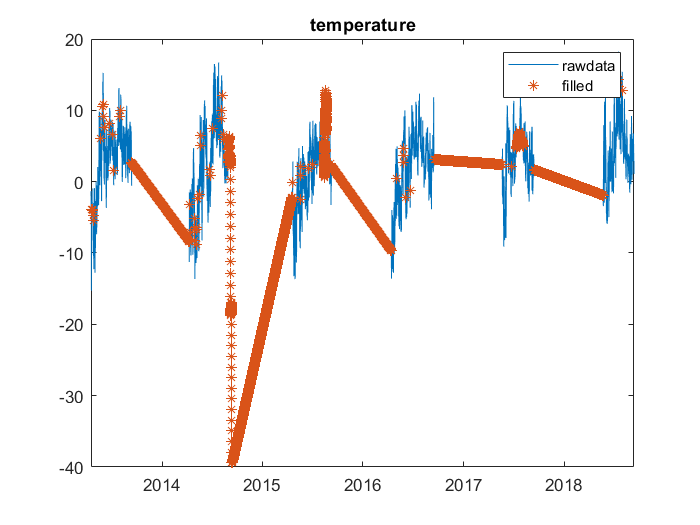

title('temperature');

[yr,mo,da,hr,mi,se,RHSummer,RHSummergaps] = timeSeriesData(timeSummer,hours(1),t1,t2,RHSummer);

Time range of the dataset 
17-Apr-2013 16:00:00-12-Sep-2018 09:00:00
27445 date gaps found 
   12-Sep-2013 12:00:00
   12-Sep-2013 13:00:00
   12-Sep-2013 14:00:00
   12-Sep-2013 15:00:00
   12-Sep-2013 16:00:00
   12-Sep-2013 17:00:00
   12-Sep-2013 18:00:00
   12-Sep-2013 19:00:00
   12-Sep-2013 20:00:00
   12-Sep-2013 21:00:00
   12-Sep-2013 22:00:00
   12-Sep-2013 23:00:00
   13-Sep-2013 00:00:00
   13-Sep-2013 01:00:00
   13-Sep-2013 02:00:00
   13-Sep-2013 03:00:00
   13-Sep-2013 04:00:00
   13-Sep-2013 05:00:00
   13-Sep-2013 06:00:00
   13-Sep-2013 07:00:00
   13-Sep-2013 08:00:00
   13-Sep-2013 09:00:00
   13-Sep-2013 10:00:00
   13-Sep-2013 11:00:00
   13-Sep-2013 12:00:00
   13-Sep-2013 13:00:00
   13-Sep-2013 14:00:00
   13-Sep-2013 15:00:00
   13-Sep-2013 16:00:00
   13-Sep-2013 17:00:00
   13-Sep-2013 18:00:00
   13-Sep-2013 19:00:00
   13-Sep-2013 20:00:00
   13-Sep-2013 21:00:00
   13-Sep-2013 22:00:00
   13-Sep-2013 23:00:00
   14-Sep-2013 00:00:00
   14-Sep-2013 01:00

28370 data gaps found 
   19-Apr-2013 13:00:00
   19-Apr-2013 14:00:00
   19-Apr-2013 15:00:00
   19-Apr-2013 16:00:00
   19-Apr-2013 17:00:00
   19-Apr-2013 18:00:00
   19-Apr-2013 19:00:00
   19-Apr-2013 20:00:00
   19-Apr-2013 21:00:00
   19-Apr-2013 22:00:00
   19-Apr-2013 23:00:00
   20-Apr-2013 00:00:00
   20-Apr-2013 01:00:00
   20-Apr-2013 02:00:00
   20-Apr-2013 03:00:00
   20-Apr-2013 04:00:00
   20-Apr-2013 05:00:00
   20-Apr-2013 06:00:00
   20-Apr-2013 07:00:00
   20-Apr-2013 08:00:00
   20-Apr-2013 09:00:00
   20-Apr-2013 10:00:00
   20-Apr-2013 11:00:00
   20-Apr-2013 12:00:00
   20-Apr-2013 13:00:00
   20-Apr-2013 14:00:00
   20-Apr-2013 15:00:00
   20-Apr-2013 16:00:00
   20-Apr-2013 17:00:00
   20-Apr-2013 18:00:00
   20-Apr-2013 19:00:00
   20-Apr-2013 20:00:00
   20-Apr-2013 21:00:00
   20-Apr-2013 22:00:00
   20-Apr-2013 23:00:00
   21-Apr-2013 00:00:00
   21-Apr-2013 01:00:00
   21-Apr-2013 02:00:00
   21-Apr-2013 03:00:00
   21-Apr-2013 04:00:00
   21-Apr-2013 05

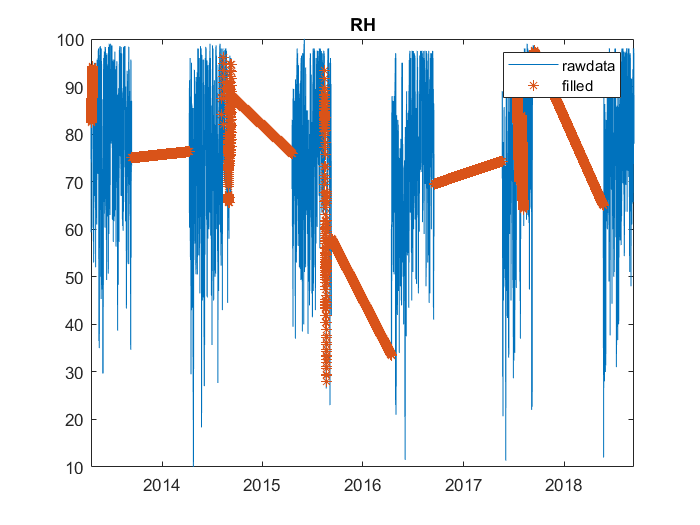

title('RH');

precSummer = table2array(rawdata(:,end));
[yr,mo,da,hr,mi,se,precSummer,precSummergaps] = timeSeriesData(timeSummer,hours(1),t1,t2,precSummer);

Time range of the dataset 
17-Apr-2013 16:00:00-12-Sep-2018 09:00:00
27445 date gaps found 
   12-Sep-2013 12:00:00
   12-Sep-2013 13:00:00
   12-Sep-2013 14:00:00
   12-Sep-2013 15:00:00
   12-Sep-2013 16:00:00
   12-Sep-2013 17:00:00
   12-Sep-2013 18:00:00
   12-Sep-2013 19:00:00
   12-Sep-2013 20:00:00
   12-Sep-2013 21:00:00
   12-Sep-2013 22:00:00
   12-Sep-2013 23:00:00
   13-Sep-2013 00:00:00
   13-Sep-2013 01:00:00
   13-Sep-2013 02:00:00
   13-Sep-2013 03:00:00
   13-Sep-2013 04:00:00
   13-Sep-2013 05:00:00
   13-Sep-2013 06:00:00
   13-Sep-2013 07:00:00
   13-Sep-2013 08:00:00
   13-Sep-2013 09:00:00
   13-Sep-2013 10:00:00
   13-Sep-2013 11:00:00
   13-Sep-2013 12:00:00
   13-Sep-2013 13:00:00
   13-Sep-2013 14:00:00
   13-Sep-2013 15:00:00
   13-Sep-2013 16:00:00
   13-Sep-2013 17:00:00
   13-Sep-2013 18:00:00
   13-Sep-2013 19:00:00
   13-Sep-2013 20:00:00
   13-Sep-2013 21:00:00
   13-Sep-2013 22:00:00
   13-Sep-2013 23:00:00
   14-Sep-2013 00:00:00
   14-Sep-2013 01:00

27445 data gaps found 
   12-Sep-2013 12:00:00
   12-Sep-2013 13:00:00
   12-Sep-2013 14:00:00
   12-Sep-2013 15:00:00
   12-Sep-2013 16:00:00
   12-Sep-2013 17:00:00
   12-Sep-2013 18:00:00
   12-Sep-2013 19:00:00
   12-Sep-2013 20:00:00
   12-Sep-2013 21:00:00
   12-Sep-2013 22:00:00
   12-Sep-2013 23:00:00
   13-Sep-2013 00:00:00
   13-Sep-2013 01:00:00
   13-Sep-2013 02:00:00
   13-Sep-2013 03:00:00
   13-Sep-2013 04:00:00
   13-Sep-2013 05:00:00
   13-Sep-2013 06:00:00
   13-Sep-2013 07:00:00
   13-Sep-2013 08:00:00
   13-Sep-2013 09:00:00
   13-Sep-2013 10:00:00
   13-Sep-2013 11:00:00
   13-Sep-2013 12:00:00
   13-Sep-2013 13:00:00
   13-Sep-2013 14:00:00
   13-Sep-2013 15:00:00
   13-Sep-2013 16:00:00
   13-Sep-2013 17:00:00
   13-Sep-2013 18:00:00
   13-Sep-2013 19:00:00
   13-Sep-2013 20:00:00
   13-Sep-2013 21:00:00
   13-Sep-2013 22:00:00
   13-Sep-2013 23:00:00
   14-Sep-2013 00:00:00
   14-Sep-2013 01:00:00
   14-Sep-2013 02:00:00
   14-Sep-2013 03:00:00
   14-Sep-2013 04

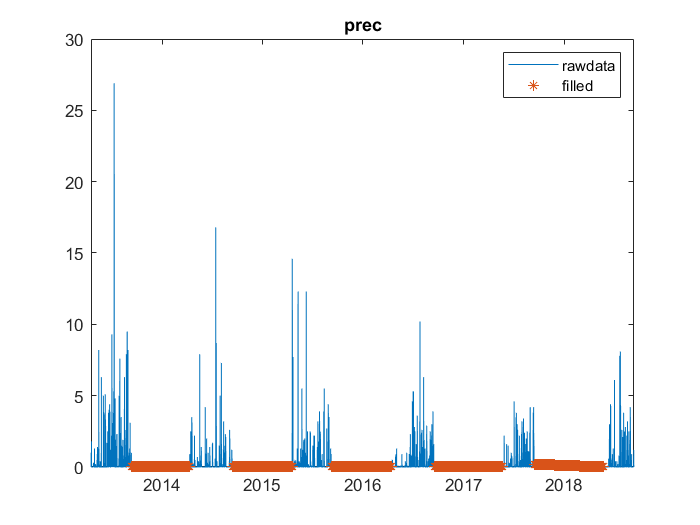

title('prec');

LWSummer = table2array(rawdata(:,8));
[yr,mo,da,hr,mi,se,LWSummer,LWSummergaps] = timeSeriesData(timeSummer,hours(1),t1,t2,LWSummer);

Time range of the dataset 
17-Apr-2013 16:00:00-12-Sep-2018 09:00:00
27445 date gaps found 
   12-Sep-2013 12:00:00
   12-Sep-2013 13:00:00
   12-Sep-2013 14:00:00
   12-Sep-2013 15:00:00
   12-Sep-2013 16:00:00
   12-Sep-2013 17:00:00
   12-Sep-2013 18:00:00
   12-Sep-2013 19:00:00
   12-Sep-2013 20:00:00
   12-Sep-2013 21:00:00
   12-Sep-2013 22:00:00
   12-Sep-2013 23:00:00
   13-Sep-2013 00:00:00
   13-Sep-2013 01:00:00
   13-Sep-2013 02:00:00
   13-Sep-2013 03:00:00
   13-Sep-2013 04:00:00
   13-Sep-2013 05:00:00
   13-Sep-2013 06:00:00
   13-Sep-2013 07:00:00
   13-Sep-2013 08:00:00
   13-Sep-2013 09:00:00
   13-Sep-2013 10:00:00
   13-Sep-2013 11:00:00
   13-Sep-2013 12:00:00
   13-Sep-2013 13:00:00
   13-Sep-2013 14:00:00
   13-Sep-2013 15:00:00
   13-Sep-2013 16:00:00
   13-Sep-2013 17:00:00
   13-Sep-2013 18:00:00
   13-Sep-2013 19:00:00
   13-Sep-2013 20:00:00
   13-Sep-2013 21:00:00
   13-Sep-2013 22:00:00
   13-Sep-2013 23:00:00
   14-Sep-2013 00:00:00
   14-Sep-2013 01:00

28642 data gaps found 
   19-Apr-2013 13:00:00
   19-Apr-2013 14:00:00
   19-Apr-2013 15:00:00
   19-Apr-2013 16:00:00
   19-Apr-2013 17:00:00
   19-Apr-2013 18:00:00
   19-Apr-2013 19:00:00
   19-Apr-2013 20:00:00
   19-Apr-2013 21:00:00
   19-Apr-2013 22:00:00
   19-Apr-2013 23:00:00
   20-Apr-2013 00:00:00
   20-Apr-2013 01:00:00
   20-Apr-2013 02:00:00
   20-Apr-2013 03:00:00
   20-Apr-2013 04:00:00
   20-Apr-2013 05:00:00
   20-Apr-2013 06:00:00
   20-Apr-2013 07:00:00
   20-Apr-2013 08:00:00
   20-Apr-2013 09:00:00
   20-Apr-2013 10:00:00
   20-Apr-2013 11:00:00
   20-Apr-2013 12:00:00
   20-Apr-2013 13:00:00
   20-Apr-2013 14:00:00
   20-Apr-2013 15:00:00
   20-Apr-2013 16:00:00
   20-Apr-2013 17:00:00
   20-Apr-2013 18:00:00
   20-Apr-2013 19:00:00
   20-Apr-2013 20:00:00
   20-Apr-2013 21:00:00
   20-Apr-2013 22:00:00
   20-Apr-2013 23:00:00
   21-Apr-2013 00:00:00
   21-Apr-2013 01:00:00
   21-Apr-2013 02:00:00
   21-Apr-2013 03:00:00
   21-Apr-2013 04:00:00
   21-Apr-2013 05

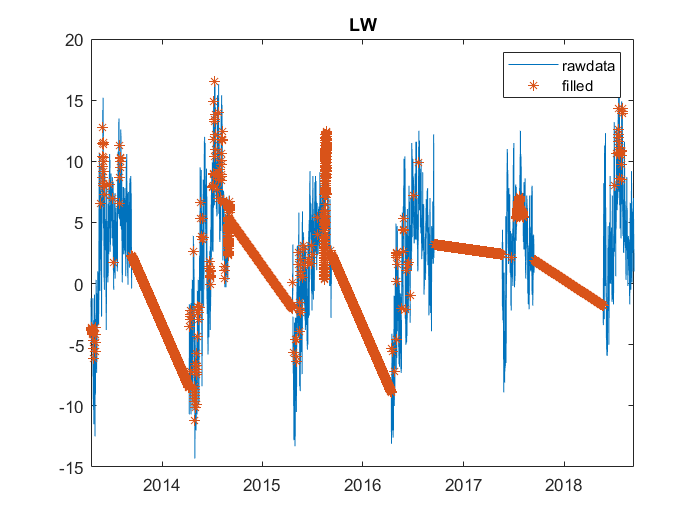

title('LW');

% save('AblationAWSsummer.mat');
% dlmwrite('check\precSummer.txt',precSummergaps);
% dlmwrite('check\tempSummer.txt',tempSummergaps);
% dlmwrite('check\LWSummer.txt',LWSummergaps);
% dlmwrite('check\RHSummer.txt',RHSummergaps);
% dlmwrite('check\precSummer.txt',datenum(rawprec));
% dlmwrite('check\tempSummer.txt',datenum(rawtemp));
% dlmwrite('check\LWSummer.txt',datenum(rawLW));
% dlmwrite('check\RHSummer.txt',datenum(rawRH));
location.N = 67:9030;   location.E = 18:5726;
location.Z = 1350;  location.ref = 'WGS84';
timeSummer = datetime(yr,mo,da,hr,mi,se);
save('SummerAWS.mat','timeSummer','RHSummer','tempSummer','LWSummer','precSummer',...
    'location','LWSummergaps','precSummergaps','tempSummergaps','RHSummergaps');
% save('SummerAWSprec.mat','timeSummer')

## SMHI Cloud

nikkaluota 1hour    Parkalompolo and Abisko 3hour

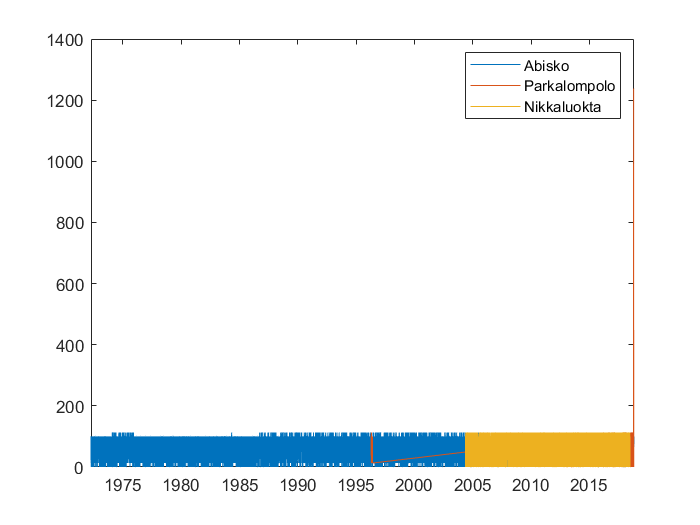

clearvars
SMHI = readtable('SMHI\smhi-RHhour.csv');
date = table2array(SMHI(:,1));  clock = table2array(SMHI(:,2));
[yr,mo,da] = ymd(date);  [hr,mi,se] = hms(clock);
timeSMHI = datetime(yr,mo,da,hr,mi,se);
RHSMHI = table2array(SMHI(:,3));
nikk = readtable('nikkaluokta\smhi-cloud.csv');
nikk(1,:) = [];
date = table2array(nikk(:,1));  clock = table2array(nikk(:,2));
[yr,mo,da] = ymd(date);  [hr,mi,se] = hms(clock);
timeNikk = datetime(yr,mo,da,hr,mi,se);
cloudNikk = table2array(nikk(:,3));
abisko = readtable('SMHI\abiskoCloud.csv');
date = table2array(abisko(:,1));  clock = table2array(abisko(:,2));
[yr,mo,da] = ymd(date);  [hr,mi,se] = hms(clock);
timeAbisko = datetime(yr,mo,da,hr,mi,se);
cloudAbisko = table2array(abisko(:,3));
park = readtable('SMHI\parkalompoloCloud.csv');
date = table2array(park(:,1));  clock = table2array(park(:,2));
[yr,mo,da] = ymd(date);  [hr,mi,se] = hms(clock);
timePark = datetime(yr,mo,da,hr,mi,se);
cloudPark = table2array(park(:,3));
% comparison
figure;
plot(timeAbisko,cloudAbisko,'DisplayName','Abisko');
hold on
plot(timePark,cloudPark,'DisplayName','Parkalompolo');
plot(timeNikk,cloudNikk,'DisplayName','Nikkaluokta');
legend

% gaps detection and filling
% t1 = timeSMHI(1);   t2 = timeSMHI(end);
% [yr,mo,da,hr,mi,se,RHSMHI,RHgaps,rawRH] = timeSeriesData(timeSMHI,hours(1),t1,t2,RHSMHI);

t1 = timeNikk(1);   t2 = timeNikk(end);
[yr,mo,da,hr,mi,se,cloudNikk,cloudNikkgaps] = timeSeriesData(timeNikk,hours(1),t1,t2,cloudNikk);

Time range of the dataset 
18-May-2004 11:00:00-02-Jul-2018 19:00:00
4086 date gaps found 
   18-May-2004 12:00:00
   18-May-2004 13:00:00
   19-May-2004 05:00:00
   21-May-2004 08:00:00
   28-May-2004 20:00:00
   30-May-2004 18:00:00
   30-May-2004 20:00:00
   03-Jun-2004 14:00:00
   04-Jun-2004 14:00:00
   04-Jun-2004 19:00:00
   04-Jun-2004 20:00:00
   07-Jun-2004 07:00:00
   07-Jun-2004 19:00:00
   07-Jun-2004 22:00:00
   07-Jun-2004 23:00:00
   09-Jun-2004 07:00:00
   09-Jun-2004 08:00:00
   10-Jun-2004 05:00:00
   10-Jun-2004 06:00:00
   10-Jun-2004 07:00:00
   10-Jun-2004 11:00:00
   10-Jun-2004 12:00:00
   10-Jun-2004 18:00:00
   11-Jun-2004 12:00:00
   22-Jun-2004 05:00:00
   25-Jun-2004 01:00:00
   25-Jun-2004 23:00:00
   26-Jun-2004 00:00:00
   26-Jun-2004 10:00:00
   26-Jun-2004 11:00:00
   26-Jun-2004 12:00:00
   26-Jun-2004 13:00:00
   26-Jun-2004 14:00:00
   01-Jul-2004 06:00:00
   01-Jul-2004 13:00:00
   04-Jul-2004 04:00:00
   05-Jul-2004 04:00:00
   05-Jul-2004 11:00:

4086 data gaps found 
   18-May-2004 12:00:00
   18-May-2004 13:00:00
   19-May-2004 05:00:00
   21-May-2004 08:00:00
   28-May-2004 20:00:00
   30-May-2004 18:00:00
   30-May-2004 20:00:00
   03-Jun-2004 14:00:00
   04-Jun-2004 14:00:00
   04-Jun-2004 19:00:00
   04-Jun-2004 20:00:00
   07-Jun-2004 07:00:00
   07-Jun-2004 19:00:00
   07-Jun-2004 22:00:00
   07-Jun-2004 23:00:00
   09-Jun-2004 07:00:00
   09-Jun-2004 08:00:00
   10-Jun-2004 05:00:00
   10-Jun-2004 06:00:00
   10-Jun-2004 07:00:00
   10-Jun-2004 11:00:00
   10-Jun-2004 12:00:00
   10-Jun-2004 18:00:00
   11-Jun-2004 12:00:00
   22-Jun-2004 05:00:00
   25-Jun-2004 01:00:00
   25-Jun-2004 23:00:00
   26-Jun-2004 00:00:00
   26-Jun-2004 10:00:00
   26-Jun-2004 11:00:00
   26-Jun-2004 12:00:00
   26-Jun-2004 13:00:00
   26-Jun-2004 14:00:00
   01-Jul-2004 06:00:00
   01-Jul-2004 13:00:00
   04-Jul-2004 04:00:00
   05-Jul-2004 04:00:00
   05-Jul-2004 11:00:00
   06-Jul-2004 18:00:00
   06-Jul-2004 19:00:00
   06-Jul-2004 20:

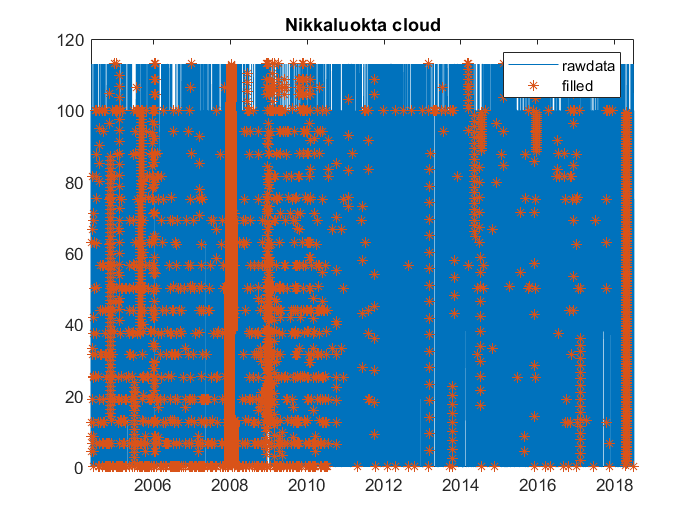

title('Nikkaluokta cloud');

timeNikk = datetime(yr,mo,da,hr,mi,se);
% t1 = timePark(1);   t2 = timePark(end);
% [yr,mo,da,hr,mi,se,cloudPark,cloudParkgaps] = timeSeriesData(timePark,hours(3),t1,t2,cloudPark);
% title('Parkalompolo cloud');
t1 = datetime(2009,01,01,06,00,00);   t2 = timeAbisko(end);
[yr,mo,da,hr,mi,se,cloudAbisko,cloudAbiskogaps] = timeSeriesData(timeAbisko,hours(1),t1,t2,cloudAbisko);

Time range of the dataset 
03-Apr-1972 18:00:00-01-Nov-2018 06:00:00
68261 date gaps found 
   01-Jan-2009 07:00:00
   01-Jan-2009 08:00:00
   01-Jan-2009 10:00:00
   01-Jan-2009 11:00:00
   01-Jan-2009 13:00:00
   01-Jan-2009 14:00:00
   01-Jan-2009 16:00:00
   01-Jan-2009 17:00:00
   01-Jan-2009 19:00:00
   01-Jan-2009 20:00:00
   01-Jan-2009 21:00:00
   01-Jan-2009 22:00:00
   01-Jan-2009 23:00:00
   02-Jan-2009 00:00:00
   02-Jan-2009 01:00:00
   02-Jan-2009 02:00:00
   02-Jan-2009 03:00:00
   02-Jan-2009 04:00:00
   02-Jan-2009 05:00:00
   02-Jan-2009 07:00:00
   02-Jan-2009 08:00:00
   02-Jan-2009 10:00:00
   02-Jan-2009 11:00:00
   02-Jan-2009 13:00:00
   02-Jan-2009 14:00:00
   02-Jan-2009 16:00:00
   02-Jan-2009 17:00:00
   02-Jan-2009 19:00:00
   02-Jan-2009 20:00:00
   02-Jan-2009 21:00:00
   02-Jan-2009 22:00:00
   02-Jan-2009 23:00:00
   03-Jan-2009 00:00:00
   03-Jan-2009 01:00:00
   03-Jan-2009 02:00:00
   03-Jan-2009 03:00:00
   03-Jan-2009 04:00:00
   03-Jan-2009 05:00

68261 data gaps found 
   01-Jan-2009 07:00:00
   01-Jan-2009 08:00:00
   01-Jan-2009 10:00:00
   01-Jan-2009 11:00:00
   01-Jan-2009 13:00:00
   01-Jan-2009 14:00:00
   01-Jan-2009 16:00:00
   01-Jan-2009 17:00:00
   01-Jan-2009 19:00:00
   01-Jan-2009 20:00:00
   01-Jan-2009 21:00:00
   01-Jan-2009 22:00:00
   01-Jan-2009 23:00:00
   02-Jan-2009 00:00:00
   02-Jan-2009 01:00:00
   02-Jan-2009 02:00:00
   02-Jan-2009 03:00:00
   02-Jan-2009 04:00:00
   02-Jan-2009 05:00:00
   02-Jan-2009 07:00:00
   02-Jan-2009 08:00:00
   02-Jan-2009 10:00:00
   02-Jan-2009 11:00:00
   02-Jan-2009 13:00:00
   02-Jan-2009 14:00:00
   02-Jan-2009 16:00:00
   02-Jan-2009 17:00:00
   02-Jan-2009 19:00:00
   02-Jan-2009 20:00:00
   02-Jan-2009 21:00:00
   02-Jan-2009 22:00:00
   02-Jan-2009 23:00:00
   03-Jan-2009 00:00:00
   03-Jan-2009 01:00:00
   03-Jan-2009 02:00:00
   03-Jan-2009 03:00:00
   03-Jan-2009 04:00:00
   03-Jan-2009 05:00:00
   03-Jan-2009 07:00:00
   03-Jan-2009 08:00:00
   03-Jan-2009 10

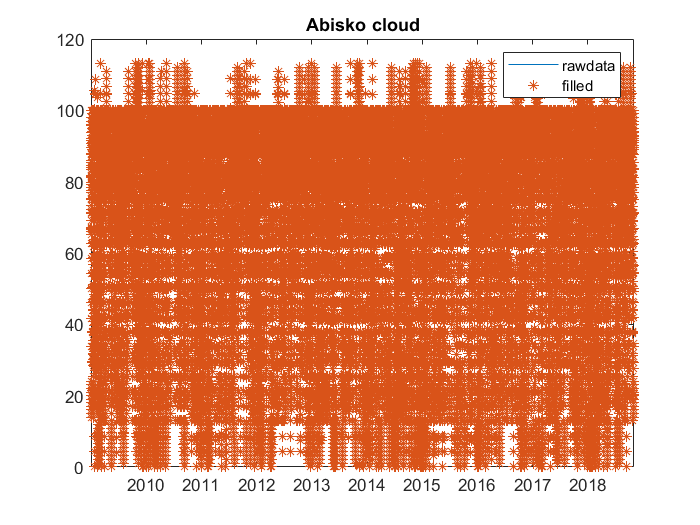

title('Abisko cloud');

timeAbisko = datetime(yr,mo,da,hr,mi,se);
% dlmwrite('check\cloudAbisko.txt',cloudAbiskogaps);
% dlmwrite('check\cloudNikk.txt',cloudNikkgaps);
% dlmwrite('check\cloudPark.txt',datenum(cloudParkgaps));
% dlmwrite('check\cloudAbisko.txt',datenum(rawAbisko));
% dlmwrite('check\cloudNikk.txt',datenum(rawNikk));
save('SMHICloud.mat','timeNikk','cloudNikk','timeAbisko','cloudAbisko','cloudAbiskogaps',...
    'cloudNikkgaps');

## SMHI AWS

clearvars
SMHI = readtable('SMHI\smhi-airThour.csv');
date = table2array(SMHI(:,1));  clock = table2array(SMHI(:,2));
[yr,mo,da] = ymd(date);  [hr,mi,se] = hms(clock);
timeSMHItemp = datetime(yr,mo,da,hr,mi,se);
timeSMHItemp = dateshift(timeSMHItemp,'start','hour');
tempSMHI = table2array(SMHI(:,3));
t1 = timeSMHItemp(1);    t2 = timeSMHItemp(end);
[yr,mo,da,hr,mi,se,tempSMHI,tempSMHIgaps] = timeSeriesData(timeSMHItemp,hours(1),t1,t2,tempSMHI);

Time range of the dataset 
21-Nov-1995 17:00:00-01-Nov-2018 06:00:00
23 repeated time found, taking the average value
17336 date gaps found 
   21-Nov-1995 18:00:00
   21-Nov-1995 21:00:00
   22-Nov-1995 00:00:00
   22-Nov-1995 03:00:00
   22-Nov-1995 09:00:00
   22-Nov-1995 15:00:00
   22-Nov-1995 21:00:00
   23-Nov-1995 00:00:00
   23-Nov-1995 03:00:00
   23-Nov-1995 09:00:00
   23-Nov-1995 15:00:00
   23-Nov-1995 21:00:00
   24-Nov-1995 00:00:00
   24-Nov-1995 03:00:00
   24-Nov-1995 09:00:00
   24-Nov-1995 15:00:00
   24-Nov-1995 16:00:00
   24-Nov-1995 21:00:00
   25-Nov-1995 00:00:00
   25-Nov-1995 03:00:00
   25-Nov-1995 04:00:00
   25-Nov-1995 09:00:00
   25-Nov-1995 13:00:00
   25-Nov-1995 14:00:00
   25-Nov-1995 15:00:00
   25-Nov-1995 17:00:00
   25-Nov-1995 20:00:00
   25-Nov-1995 21:00:00
   26-Nov-1995 00:00:00
   26-Nov-1995 01:00:00
   26-Nov-1995 03:00:00
   26-Nov-1995 05:00:00
   26-Nov-1995 09:00:00
   26-Nov-1995 10:00:00
   26-Nov-1995 15:00:00
   26-Nov-1995 21:0

17336 data gaps found 
   21-Nov-1995 18:00:00
   21-Nov-1995 21:00:00
   22-Nov-1995 00:00:00
   22-Nov-1995 03:00:00
   22-Nov-1995 09:00:00
   22-Nov-1995 15:00:00
   22-Nov-1995 21:00:00
   23-Nov-1995 00:00:00
   23-Nov-1995 03:00:00
   23-Nov-1995 09:00:00
   23-Nov-1995 15:00:00
   23-Nov-1995 21:00:00
   24-Nov-1995 00:00:00
   24-Nov-1995 03:00:00
   24-Nov-1995 09:00:00
   24-Nov-1995 15:00:00
   24-Nov-1995 16:00:00
   24-Nov-1995 21:00:00
   25-Nov-1995 00:00:00
   25-Nov-1995 03:00:00
   25-Nov-1995 04:00:00
   25-Nov-1995 09:00:00
   25-Nov-1995 13:00:00
   25-Nov-1995 14:00:00
   25-Nov-1995 15:00:00
   25-Nov-1995 17:00:00
   25-Nov-1995 20:00:00
   25-Nov-1995 21:00:00
   26-Nov-1995 00:00:00
   26-Nov-1995 01:00:00
   26-Nov-1995 03:00:00
   26-Nov-1995 05:00:00
   26-Nov-1995 09:00:00
   26-Nov-1995 10:00:00
   26-Nov-1995 15:00:00
   26-Nov-1995 21:00:00
   27-Nov-1995 00:00:00
   27-Nov-1995 03:00:00
   27-Nov-1995 08:00:00
   27-Nov-1995 09:00:00
   27-Nov-1995 14

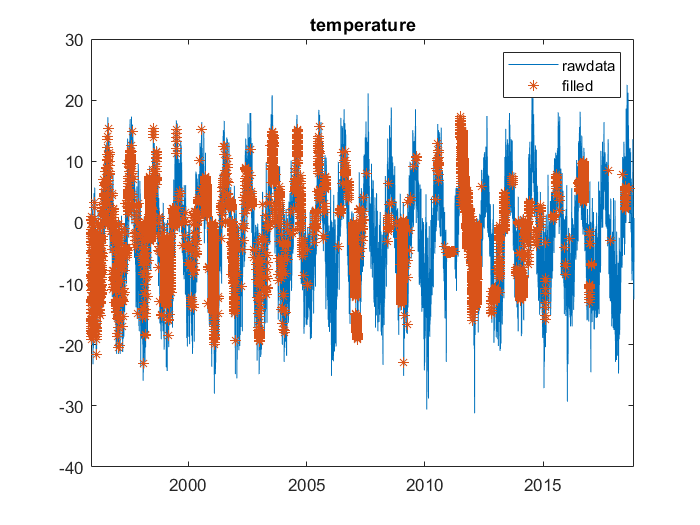

timeSMHItemp = datetime(yr,mo,da,hr,mi,se);
title('temperature');

SMHI = readtable('SMHI\smhi-RHhour.csv');
date = table2array(SMHI(:,1));  clock = table2array(SMHI(:,2));
[yr,mo,da] = ymd(date);  [hr,mi,se] = hms(clock);
timeSMHIrh = datetime(yr,mo,da,hr,mi,se);
timeSMHIrh = dateshift(timeSMHIrh,'start','hour');
rhSMHI = table2array(SMHI(:,3));
t1 = timeSMHIrh(1);    t2 = timeSMHIrh(end);
[yr,mo,da,hr,mi,se,rhSMHI,rhSMHIgaps] = timeSeriesData(timeSMHIrh,hours(1),t1,t2,rhSMHI);

Time range of the dataset 
21-Nov-1995 11:00:00-01-Nov-2018 06:00:00
19597 date gaps found 
   24-Nov-1995 16:00:00
   25-Nov-1995 04:00:00
   25-Nov-1995 13:00:00
   25-Nov-1995 14:00:00
   25-Nov-1995 17:00:00
   25-Nov-1995 18:00:00
   25-Nov-1995 20:00:00
   26-Nov-1995 01:00:00
   26-Nov-1995 05:00:00
   26-Nov-1995 06:00:00
   26-Nov-1995 10:00:00
   26-Nov-1995 21:00:00
   27-Nov-1995 02:00:00
   27-Nov-1995 08:00:00
   27-Nov-1995 14:00:00
   27-Nov-1995 15:00:00
   27-Nov-1995 17:00:00
   27-Nov-1995 18:00:00
   27-Nov-1995 19:00:00
   27-Nov-1995 20:00:00
   27-Nov-1995 21:00:00
   27-Nov-1995 22:00:00
   27-Nov-1995 23:00:00
   28-Nov-1995 01:00:00
   28-Nov-1995 02:00:00
   28-Nov-1995 10:00:00
   28-Nov-1995 17:00:00
   30-Nov-1995 21:00:00
   03-Dec-1995 09:00:00
   06-Dec-1995 16:00:00
   07-Dec-1995 12:00:00
   08-Dec-1995 00:00:00
   08-Dec-1995 11:00:00
   08-Dec-1995 16:00:00
   08-Dec-1995 21:00:00
   09-Dec-1995 08:00:00
   10-Dec-1995 06:00:00
   11-Dec-1995 09:00

19597 data gaps found 
   24-Nov-1995 16:00:00
   25-Nov-1995 04:00:00
   25-Nov-1995 13:00:00
   25-Nov-1995 14:00:00
   25-Nov-1995 17:00:00
   25-Nov-1995 18:00:00
   25-Nov-1995 20:00:00
   26-Nov-1995 01:00:00
   26-Nov-1995 05:00:00
   26-Nov-1995 06:00:00
   26-Nov-1995 10:00:00
   26-Nov-1995 21:00:00
   27-Nov-1995 02:00:00
   27-Nov-1995 08:00:00
   27-Nov-1995 14:00:00
   27-Nov-1995 15:00:00
   27-Nov-1995 17:00:00
   27-Nov-1995 18:00:00
   27-Nov-1995 19:00:00
   27-Nov-1995 20:00:00
   27-Nov-1995 21:00:00
   27-Nov-1995 22:00:00
   27-Nov-1995 23:00:00
   28-Nov-1995 01:00:00
   28-Nov-1995 02:00:00
   28-Nov-1995 10:00:00
   28-Nov-1995 17:00:00
   30-Nov-1995 21:00:00
   03-Dec-1995 09:00:00
   06-Dec-1995 16:00:00
   07-Dec-1995 12:00:00
   08-Dec-1995 00:00:00
   08-Dec-1995 11:00:00
   08-Dec-1995 16:00:00
   08-Dec-1995 21:00:00
   09-Dec-1995 08:00:00
   10-Dec-1995 06:00:00
   11-Dec-1995 09:00:00
   11-Dec-1995 14:00:00
   11-Dec-1995 18:00:00
   12-Dec-1995 05

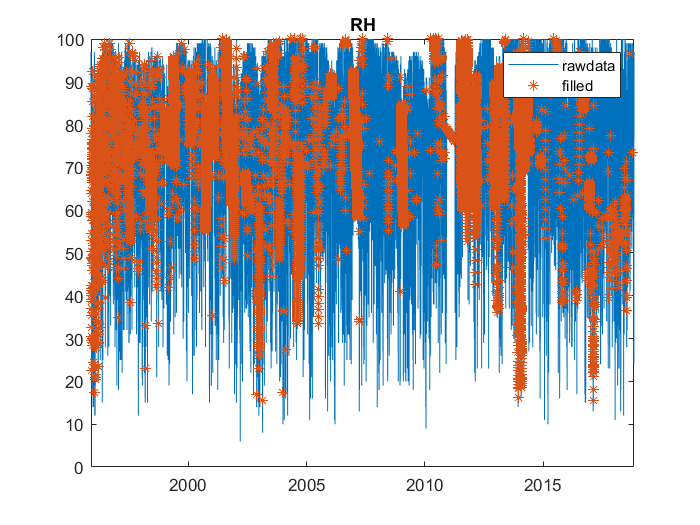

timeSMHIrh = datetime(yr,mo,da,hr,mi,se);
title('RH');

save('SMHI\SMHIAWS.mat','timeSMHIrh','timeSMHItemp','tempSMHI','rhSMHI','rhSMHIgaps',...
    'tempSMHIgaps');

## time series gaps summary

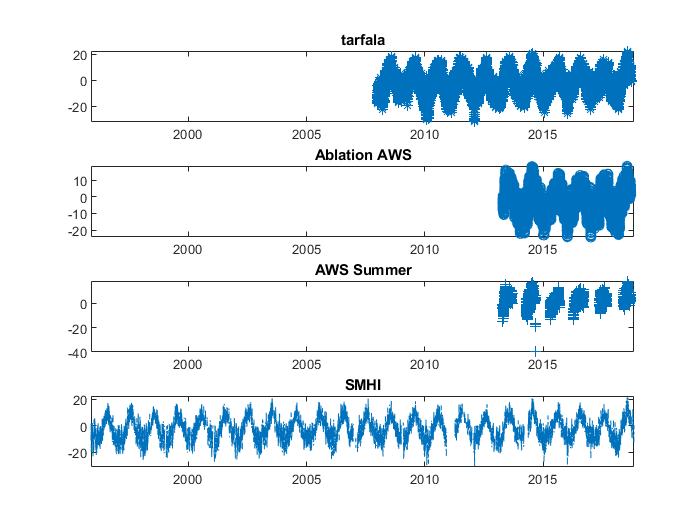

clearvars;  close all
load('AblationAWS.mat');    load('TarfalaAWS.mat');
load('SummerAWS.mat');      load('SMHICloud.mat');  load('SMHI\SMHIAWS.mat');



figure 

ax1 = subplot(4,1,1);
index = nan(size(tempTRSgaps));   index(~tempTRSgaps) = 1;
plot(timeTarfala, tempTRS.*index,'-*','DisplayName','tarfala');
title('tarfala');
ax2 = subplot(4,1,2);
index = nan(size(tempAWSgaps));   index(~tempAWSgaps) = 1;
plot(timeAWS, tempAWS.*index,'-o','DisplayName','AWS');
title('Ablation AWS');
ax3 = subplot(4,1,3);
index = nan(size(tempSummergaps));   index(~tempSummergaps) = 1;
plot(timeSummer, tempSummer.*index,'-+','DisplayName','AWSSummer');
title('AWS Summer');
ax4 = subplot(4,1,4);
index = nan(size(tempSMHIgaps));   index(~tempSMHIgaps) = 1;
plot(timeSMHItemp, tempSMHI.*index,'-.','DisplayName','SMHI');
title('SMHI');
% legend;
linkaxes([ax1, ax2, ax3, ax4],'x');

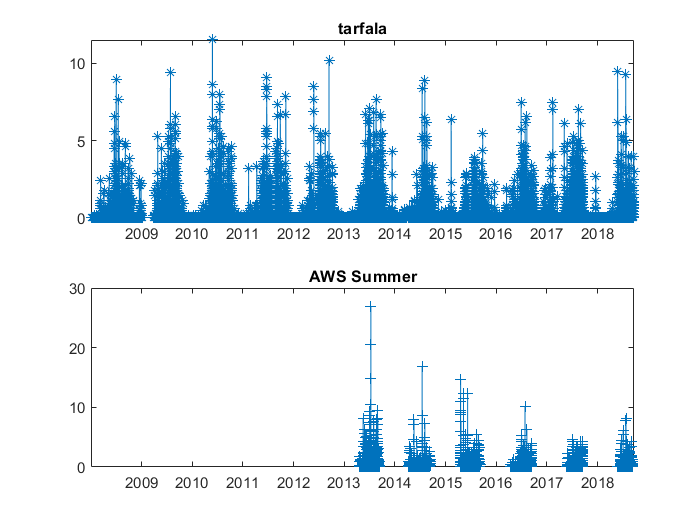


figure;
% title('precipitation mm');
ax1 = subplot(2,1,1);
index = nan(size(precTRSgaps));   index(~precTRSgaps) = 1;
plot(timeTarfala, precTRS.*index,'-*','DisplayName','tarfala');
title('tarfala');
ax2 = subplot(2,1,2);
index = nan(size(precSummergaps));   index(~precSummergaps) = 1;
plot(timeSummer, precSummer.*index,'-+','DisplayName',...
    'AWSSummer');
title('AWS Summer');
% legend
linkaxes([ax1, ax2],'x');

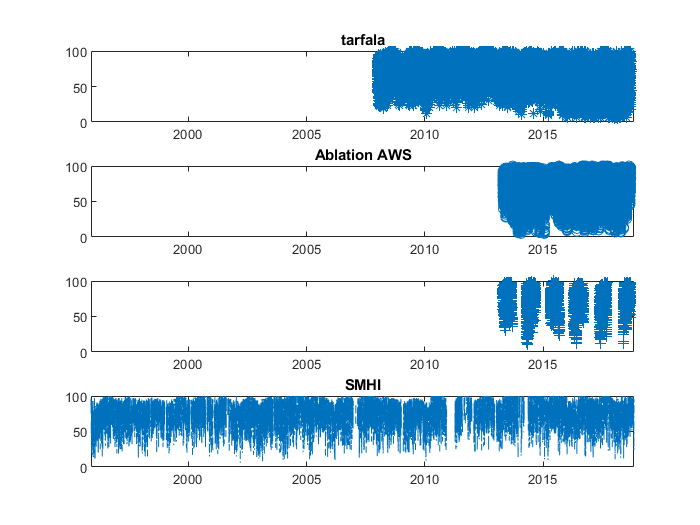


figure;
% title('RH')
ax1 = subplot(4,1,1);
index = nan(size(RHTRSgaps));   index(~RHTRSgaps) = 1;
plot(timeTarfala, RHTRS.*index,'-*','DisplayName','tarfala');
title('tarfala');
ax2 = subplot(4,1,2);
index = nan(size(RHAWSgaps));   index(~RHAWSgaps) = 1;
plot(timeAWS, RHAWS.*index,'-o','DisplayName','AWS');
title('Ablation AWS');
ax3 = subplot(4,1,3);
index = nan(size(RHSummergaps));   index(~RHSummergaps) = 1;
plot(timeSummer, RHSummer.*index,'-+','DisplayName','AWSSummer');
ax4 = subplot(4,1,4);
index = nan(size(rhSMHIgaps));   index(~rhSMHIgaps) = 1;
plot(timeSMHIrh, rhSMHI.*index,'-.','DisplayName',...
    'SMHI');
title('SMHI');
% legend
linkaxes([ax1, ax2, ax3, ax4],'x');

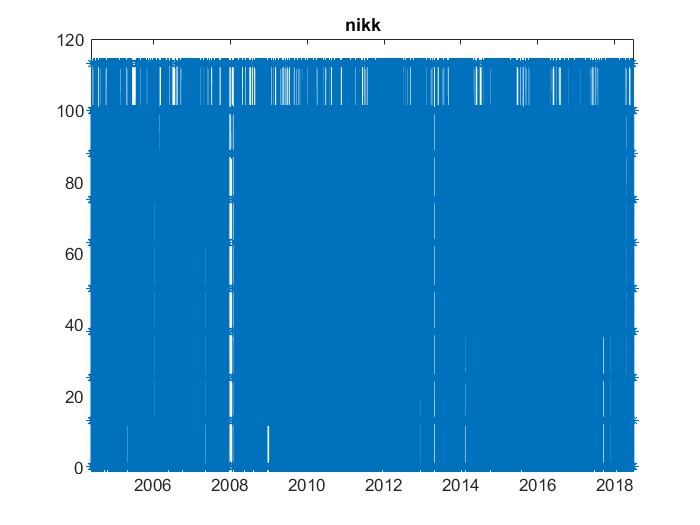


figure;
% % title('cloud');
% x1 = subplot(2,1,1);
% index = nan(size(cloudAbiskogaps));   index(~cloudAbiskogaps) = 1;
% plot(timeAbisko, cloudAbisko.*index,'-o','DisplayName',...
%     'Abisko');
% title('Abisko');
% ax2 = subplot(2,1,2);
index = nan(size(cloudNikkgaps));   index(~cloudNikkgaps) = 1;
plot(timeNikk, cloudNikk.*index,'-*','DisplayName','Nikk');
title('nikk');

% linkaxes([ax1, ax2],'x');

## function

function [time,data] = climateInput(filepath,fileout)
subdir = dir(filepath);
numfile = length(subdir);
for i = 3:numfile
    rawdata = readtable([filepath, subdir(i).name]);
    time = rawdata.Var1;
    data = rawdata.Var2;
    [y,m,d] = ymd(time);
    [hr,mi,se] = hms(time);
    dlmwrite(fileout,[y,m,d,hr,mi,se,data],'-append');
end
rawdata = dlmread(fileout);
time = datetime(rawdata(:,1:6));
data = rawdata(:,7);
% figure;
% plot(time,data);
% title(fileout);
end